# Atividade 02_01

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## **Logical Indexing**

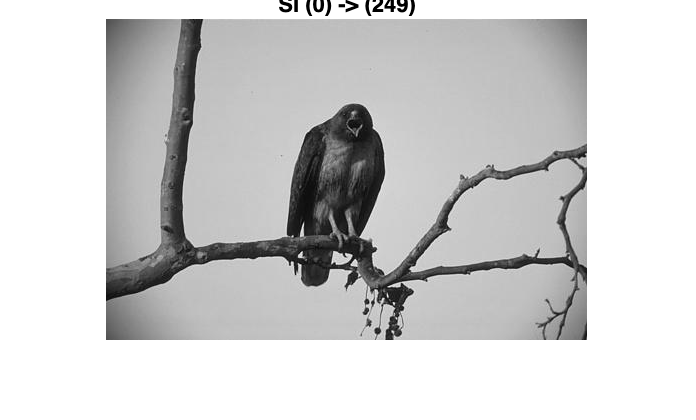

% source image
SI = imread('42049.jpg');
[SIMin, SIMax] = bounds(SI(:));


% processed image
PI = SI;
PI(PI < 20) = 20;
PI(PI > 200) = 200;
[PIMin, PIMax] = bounds(PI(:));

% Show difference
figure, imshow(SI), title("SI (" + SIMin + ") -> (" + SIMax + ")")

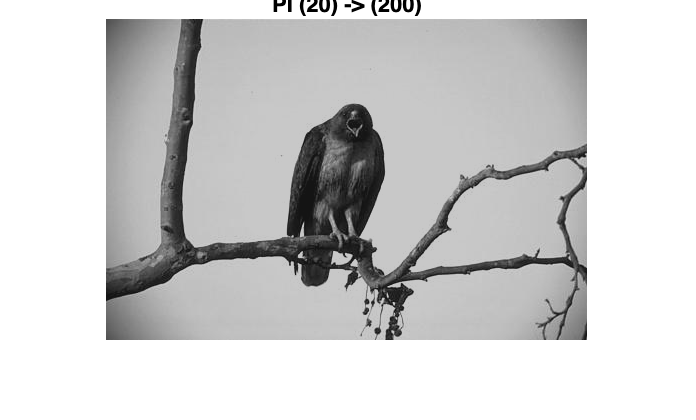

figure, imshow(PI), title("PI (" + PIMin + ") -> (" + PIMax + ")")


% Save processed image
imwrite(PI, '42049_20-200.png');